# Time domain response

## 1st order system

clear; 
s=tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.



Tc=10 %time constant

Tc = 10

G=1/(Tc*s)

G =
 
   1
  ----
  10 s
 
연속시간 전달 함수입니다.




T=feedback(G,1)

T =
 
     1
  --------
  10 s + 1
 
연속시간 전달 함수입니다.



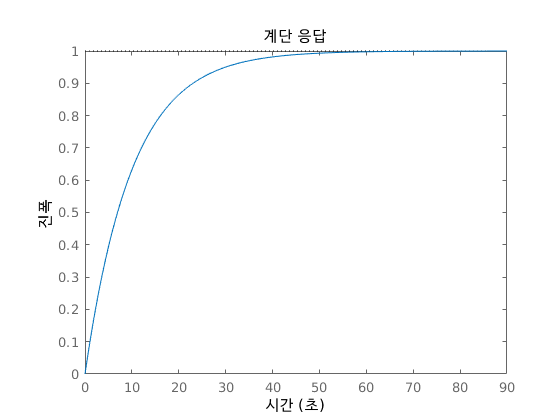

step(T)

t=0:0.1:90

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


alpha=1

alpha = 1

u=alpha*t         % ramp signal

u =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


[y,t]=lsim(T,u,t)

y =          0
    0.0005
    0.0020
    0.0045
    0.0079
    0.0123
    0.0176
    0.0239
    0.0312
    0.0393


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


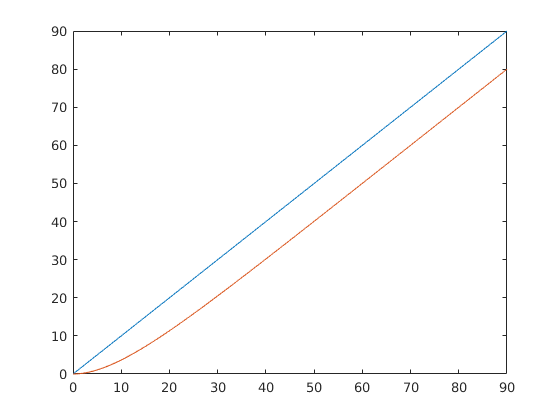

plot(t,u,t,y)

Alternatively

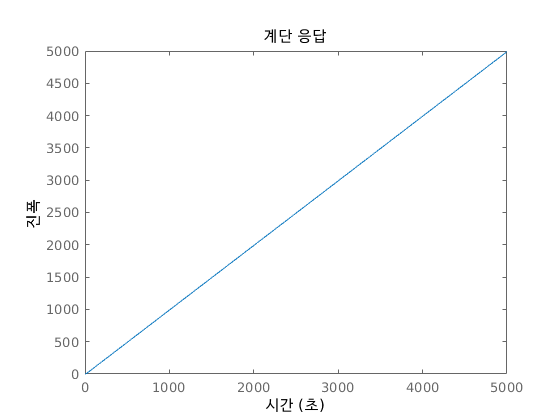

step(T/s) % ramp response

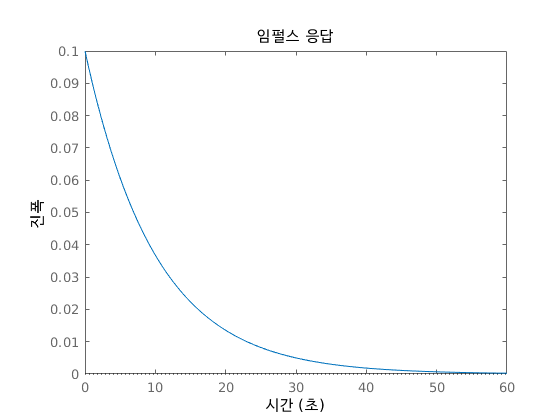

impulse(T)

## 2nd order system

clear all; 
s=tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.



zeta=0.2; wn=10;
G=wn^2/(s^2+2*zeta*wn*s+wn^2)

G =
 
        100
  ---------------
  s^2 + 4 s + 100
 
연속시간 전달 함수입니다.



zpk(G)

ans =
 
        100
  ----------------
  (s^2 + 4s + 100)
 
연속시간 영점/극점/이득 모델입니다.





pole(G)

ans =   -2.0000 + 9.7980i
  -2.0000 - 9.7980i


[myzero, myk]=zero(G)


myzero =

  0×1 비어 있는 double 열 벡터



myk = 100

Pole zero map

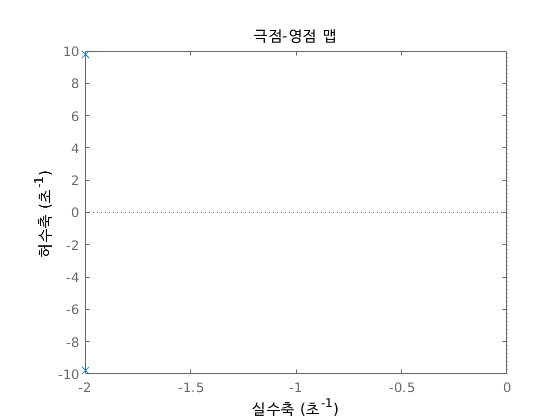

pzmap(G)

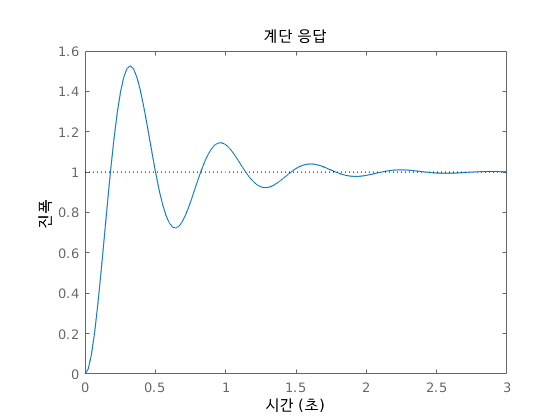

step(G)

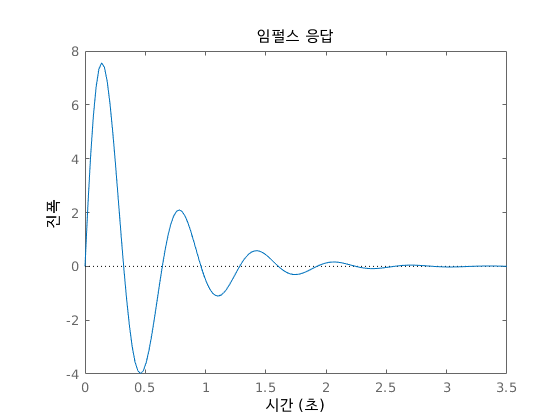

impulse(G)

Step response comparison wrt \zeta 

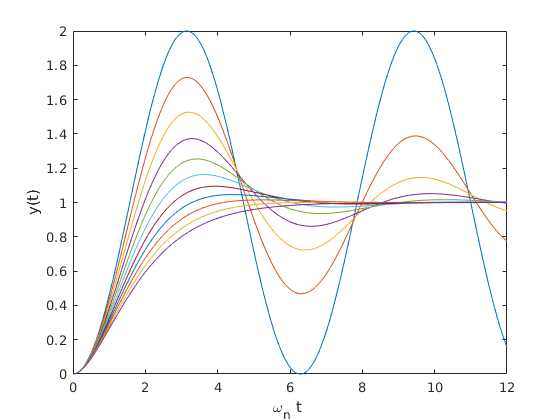

clear all;
t=0:.0001:12;
zeta=0;den=[1 2*zeta 1];y1=step(1,den,t);
zeta=.1;den=[1 2*zeta 1];y2=step(1,den,t);
zeta=.2;den=[1 2*zeta 1];y3=step(1,den,t);
zeta=.3;den=[1 2*zeta 1];y4=step(1,den,t);
zeta=.4;den=[1 2*zeta 1];y5=step(1,den,t);
zeta=.5;den=[1 2*zeta 1];y6=step(1,den,t);
zeta=.6;den=[1 2*zeta 1];y7=step(1,den,t);
zeta=.7;den=[1 2*zeta 1];y8=step(1,den,t);
zeta=.8;den=[1 2*zeta 1];y9=step(1,den,t);
zeta=.9;den=[1 2*zeta 1];y10=step(1,den,t);
zeta=1;den=[1 2*zeta 1];y11=step(1,den,t);

plot(t,y1,t,y2,t,y3,t,y4,t,y5,t,y6,t,y7,t,y8,t,y9,t,y10,t,y11)
axis([0 12 0 2]);
xlabel('\omega_n t ');ylabel('y(t)');

Impulse response comparison wrt \zeta 

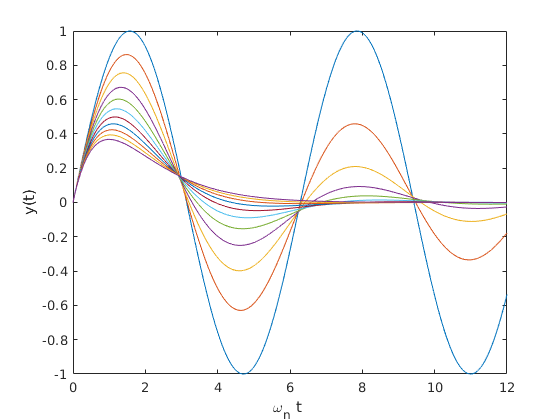

zeta=0;den=[1 2*zeta 1];y1=impulse(1,den,t);
zeta=.1;den=[1 2*zeta 1];y2=impulse(1,den,t);
zeta=.2;den=[1 2*zeta 1];y3=impulse(1,den,t);
zeta=.3;den=[1 2*zeta 1];y4=impulse(1,den,t);
zeta=.4;den=[1 2*zeta 1];y5=impulse(1,den,t);
zeta=.5;den=[1 2*zeta 1];y6=impulse(1,den,t);
zeta=.6;den=[1 2*zeta 1];y7=impulse(1,den,t);
zeta=.7;den=[1 2*zeta 1];y8=impulse(1,den,t);
zeta=.8;den=[1 2*zeta 1];y9=impulse(1,den,t);
zeta=.9;den=[1 2*zeta 1];y10=impulse(1,den,t);
zeta=1;den=[1 2*zeta 1];y11=impulse(1,den,t);

plot(t,y1,t,y2,t,y3,t,y4,t,y5,t,y6,t,y7,t,y8,t,y9,t,y10,t,y11)
axis([0 12 -1 1]);
xlabel('\omega_n t ');ylabel('y(t)');

## Higher order system

clear all; 
s=tf('s');
G=62.5*(s+2.5)/((s^2+6*s+25)*(s+6.25))

G =
 
           62.5 s + 156.2
  --------------------------------
  s^3 + 12.25 s^2 + 62.5 s + 156.2
 
연속시간 전달 함수입니다.



zpk(G)

ans =
 
        62.5 (s+2.5)
  ------------------------
  (s+6.25) (s^2 + 6s + 25)
 
연속시간 영점/극점/이득 모델입니다.



pole(G)

ans =   -6.2500 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i


zero(G)

ans = -2.5000

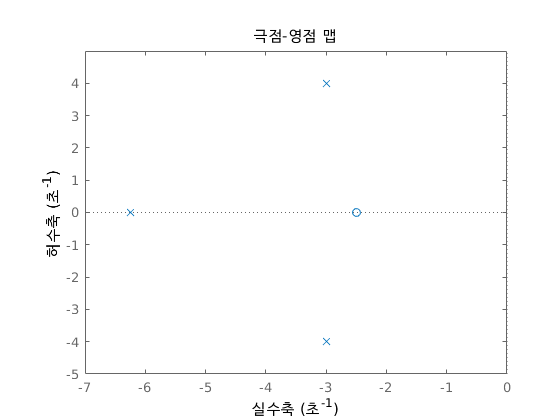

pzmap(G)

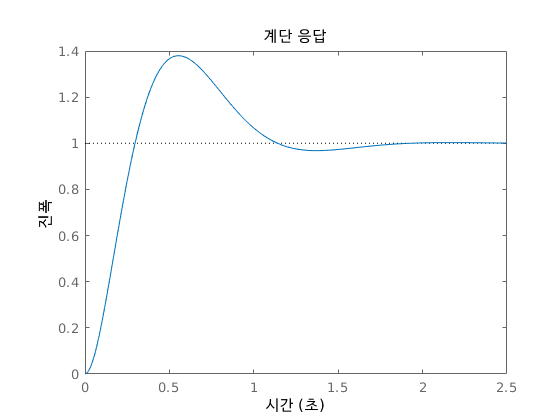

step(G)

G1=(s+2.5)/(s^2+6*s+25)

G1 =
 
     s + 2.5
  --------------
  s^2 + 6 s + 25
 
연속시간 전달 함수입니다.



G2=1/(s+6.25)

G2 =
 
     1
  --------
  s + 6.25
 
연속시간 전달 함수입니다.



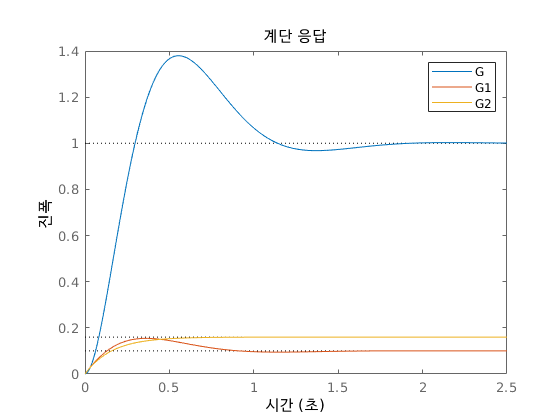

step(G,G1,G2)
legend('G','G1','G2');

Gapx=G1

Gapx =
 
     s + 2.5
  --------------
  s^2 + 6 s + 25
 
연속시간 전달 함수입니다.



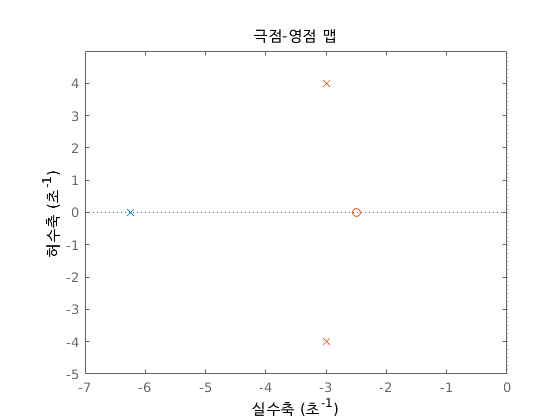

pzmap(G,Gapx)

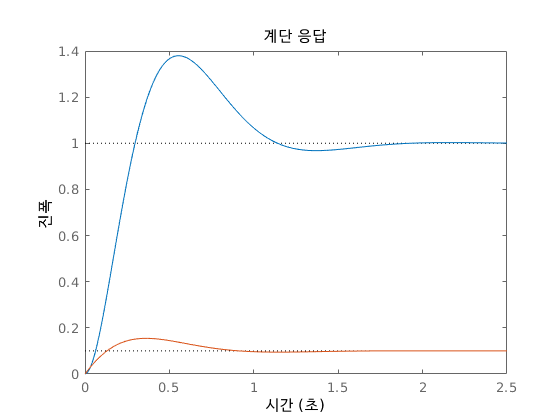

step(G,Gapx)

## Transient Respose specification (2nd order sys.)

clear all; 
s=tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.



zeta=0.15; wn=1;
G=wn^2/(s^2+2*zeta*wn*s+wn^2)

G =
 
         1
  ---------------
  s^2 + 0.3 s + 1
 
연속시간 전달 함수입니다.



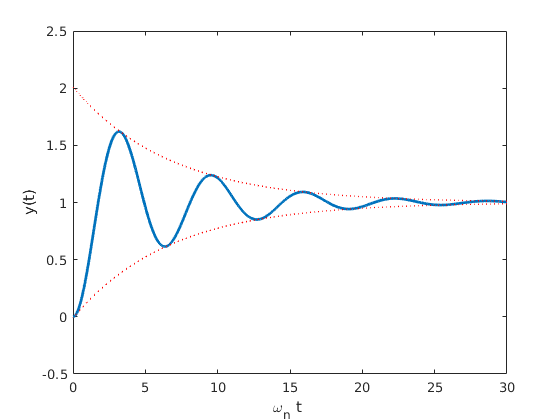


t=0:.001:30;
y=step(G,t);
plot(t,y,'LineWidth',2); hold on
ye=1/sqrt(1-zeta^2)*exp(-zeta*wn*t); %envelop function
plot(t,1+ye,':r','LineWidth',1)
plot(t,1-ye,':r','LineWidth',1),
xlabel('\omega_n t ');ylabel('y(t)');

Transient Response Characteristics

stepinfo(G)

ans = 다음 필드를 포함한 struct :
        RiseTime: 1.1759
    SettlingTime: 25.8532
     SettlingMin: 0.6161
     SettlingMax: 1.6173
       Overshoot: 61.7253
      Undershoot: 0
            Peak: 1.6173
        PeakTime: 3.0701
